# Test Mappings

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
% Define dimension of modes
SSMDim = 6; hSSMDim = SSMDim/2;
load obsDecayDataC

## Visualize Training Data

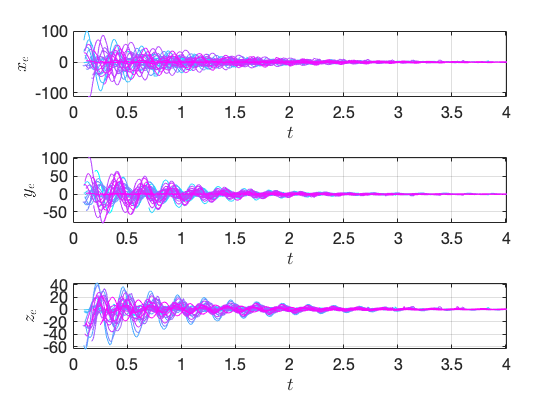

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

tipData = oData;
Ts = 1/(tipData{iTraj,1}(2)-tipData{iTraj,1}(1));
freqHz = 15;
for iTraj = 1:size(oData, 1)
    tipData{iTraj,2} = oData{iTraj,2}(trajs,:);%transpose(lowpass(transpose(oData{iTraj,2}(trajs,:)), freqHz, Ts));
end

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

tipData = 39×2 cell array
    {[                                                                      0.2001 0.2100 0.2200 0.2300 0.2400 0.2500 0.2601 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 0.3401 0.3500 0.3600 0.3700 0.3803 0.3900 0.4000 0.4100 0.4200 0.4299 0.4400 0.4500 0.4600 0.4700 0.4800 0.4899 0.5000 0.5100 0.5200 0.5300 0.5401 0.5500 0.5600 0.5700 0.5800 0.5899 0.6000 0.6100 0.6200 0.6300 0.6400 0.6499 0.6600 0.6699 0.6800 0.6900 0.7000 0.7100 0.7200 0.7300 0.7400 0.7500 0.7603 0.7699 0.7800 0.7901 0.8000 0.8100 0.8200 0.8299 0.8400 0.8500 0.8602 0.8700 0.8800 0.8900 0.8999 0.9100 0.9200 0.9300 0.9400 0.9500 0.9600 0.9700 0.9800 0.9900 1.0000 1.0104 1.0200 1.0299 1.0400 1.0500 1.0600 1.0700 1.0800 1.0900 1.1000 1.1100 1.1200 1.1300 1.1400 1.1500 1.1600 1.1700 1.1800 1.1899 1.2000 1.2099 1.2200 1.2300 1.2400 1.2500 1.2600 1.2700 1.2800 1.2900 1.3000 1.3100 1.3200 1.3299 1.3400 1.3499 1.3600 1.3700 1.3800 1.3900 1.4000 1.4100 1.4201 1.4299 1.4400 1.4500 1.4600 1.4700 1.

Visualize filtered data

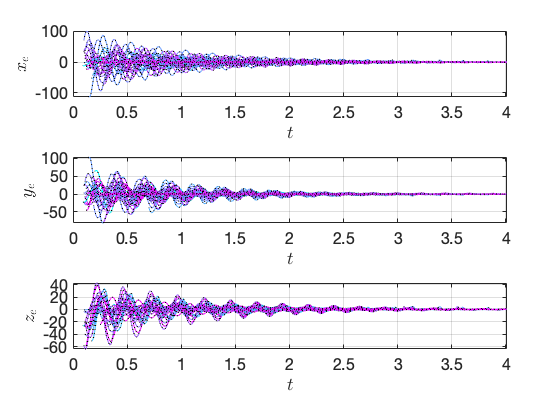

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
        plot(tipData{iTraj,1},tipData{iTraj,2}(iObs,:), 'k:', 'Linewidth',1)
    end
end

Perform delay-embedding. As observables for the model, we consider the current tip position data as well as past measurements (no future ones) of the tip position data. For this case (we only consider the tip), we have a minimum of `4` delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `4+overEmbed`. We also do some cutting, but it is not necessary in this current case.

overEmbed = 5;
[yData, opts_embd] = coordinatesEmbeddingControl(tipData, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);

PCA is still useful in the delay-embeeded space, as the number of modes explaining most of the data should be the dimension of the SSM. Indeed, we get it as more than 90% of variance is explained by the first six PCA modes.

disp('PCA')

PCA


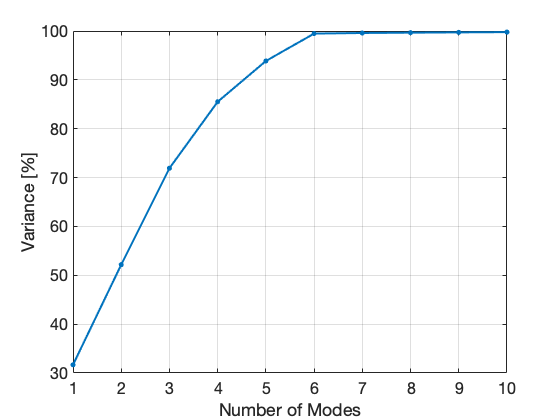

Xsnapshots = cat(2,yDataTrunc{:,2});
% Perform SVD on displacement field
[V,S,~] = svd(Xsnapshots, 0);
% Note we assume data centered around the origin, which is the
% fixed point of our system
customFigure;
maxModesPlot = 10;
l2vals = diag(S).^2;
plot(1:length(l2vals),cumsum(l2vals)/sum(l2vals)*100,'.-','Linewidth',2,'MarkerSize',12)
xlabel('Number of Modes');
ylabel('Variance [%]');
xlim([1 maxModesPlot])
set(gca,'XTick',[1:1:maxModesPlot])


Vde = V(:,1:SSMDim);
% Set reduced-coordinates as PCA projection to the first six modes
etaDataTrunc = yDataTrunc;
for iTraj = 1:size(oData, 1)
    etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
end

% Set test and train trajectories
indTest = [5 15 21 32 38];
indTrain = setdiff(1:size(oData, 1),indTest);

## Geometry

Manifold fitting with prescribed graph. Higher orders tend to overfit.

SSMOrder = 3;
if SSMOrder == 1
    % Need to recompute as the columns of Vde might change in order
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
    Vde = IMInfo.parametrization.tangentSpaceAtOrigin;
    etaDataTrunc = yDataTrunc;
    for iTraj = 1:size(oData, 1)
        etaDataTrunc{iTraj,2} = transpose(Vde)*yDataTrunc{iTraj,2};
    end
else
    IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder,'reducedCoordinates',etaDataTrunc(indTrain,:));
    IMInfo.chart.map = @(x) transpose(Vde)*x;
end

Evaluate learning of geometry.

%% Trajectory lifting requires reduced coordinates (ensures y is on manifold, 
% hence yRec =/= yDataTrunc)
disp('Results of geometry fit:')

Results of geometry fit:


yRec = liftTrajectories(IMInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
meanErrorGeoTrain = mean(normedTrajDist(indTrain))*100

meanErrorGeoTrain = 1.7038

meanErrorGeoTest = mean(normedTrajDist(indTest))*100

meanErrorGeoTest = 1.6122

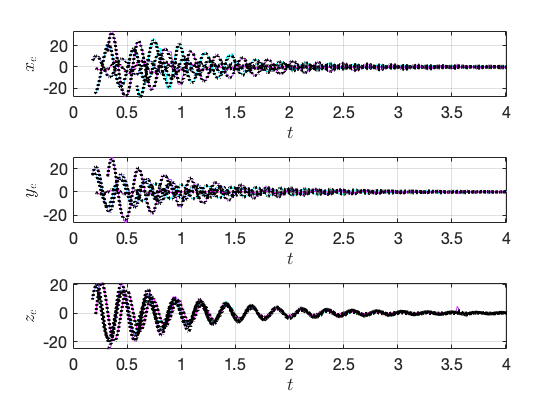


% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Reduced dynamics

Cubic order dynamics halves the trajectory error of linear dynamics. The `Map` case seems more accurate than the `Flow` one.

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'default');

Estimation of the reduced dynamics...  Done. 


RDInfo.eigenvaluesLinPartFlow(1:3)

ans =   -0.8733 +25.8972i
  -1.1506 +26.2356i
  -1.2191 +26.6590i


Rauton = RDInfo.reducedDynamics.map

Rauton = function_handle with value:
    @(x)W_r*phi(x)


Evaluate learning of reduced dynamics.

disp('Errors for the dynamics on reduced-coordinates:')

Errors for the dynamics on reduced-coordinates:


etaRec = advectRD(RDInfo, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(etaRec, etaDataTrunc);
meanErrorDynTrain = mean(normedTrajDist(indTrain))*100

meanErrorDynTrain = Inf

meanErrorDynTest = mean(normedTrajDist(indTest))*100

meanErrorDynTest = 10.5672

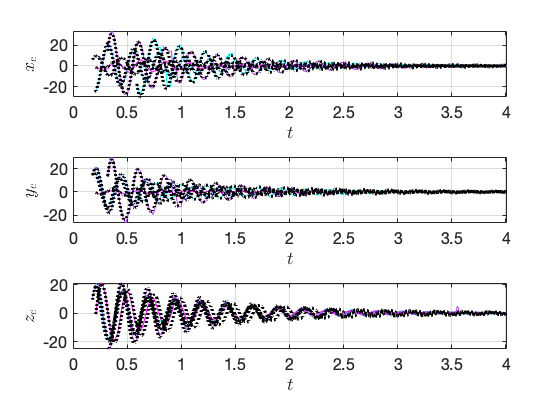

yRec = liftTrajectories(IMInfo, etaRec);

% Plot test data
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
labels = ["$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yData{indTest(iTraj),1},yData{indTest(iTraj),2}(outdofs(iObs),:),'Linewidth',1)
    end
end
for iTraj = 1:length(indTest)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yRec{indTest(iTraj),1},yRec{indTest(iTraj),2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end

## Check mapping from observables to observables (with inputs)

$v:\Re^n \to \Re^p$ is the mapping from $\mathit{\mathbf{y}}$ to $\bar{\mathit{\mathbf{x}}}$ 

$w:\Re^p \to \Re^n$ is the mapping from $\bar{\mathit{\mathbf{x}}}$ to $\mathit{\mathbf{y}}$ 

%load koopman_data_figureEight

% Load and process tpwl data for tip coords only
load tpwl_data
y = y(13:end, :);

% Testing mapping function
zu = {};
zu{1, 1} = t; zu{1, 2} = y - y(:, end);
% zu{1, 1} = tipData{1,1}; zu{1, 2} = tipData{1,2};
[yDataInput, Yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.



% v then w mapping
yDataRemapped = yDataInput;
xData = yDataInput;
for iTraj = 1:size(yDataInput, 1)
    xData{iTraj, 2} = transpose(Vde) * yDataInput{iTraj, 2}; % Project down
    yDataRemapped = liftTrajectories(IMInfo, xData); % Project up
    % yDataRemapped{iTraj, 2} = Vde * xData{iTraj, 2}; % Project up with standard projection
end


Plot $\mathit{\mathbf{y}}=\left(w\circ v\right)\left(\mathit{\mathbf{y}}\right)$. Expect similar results

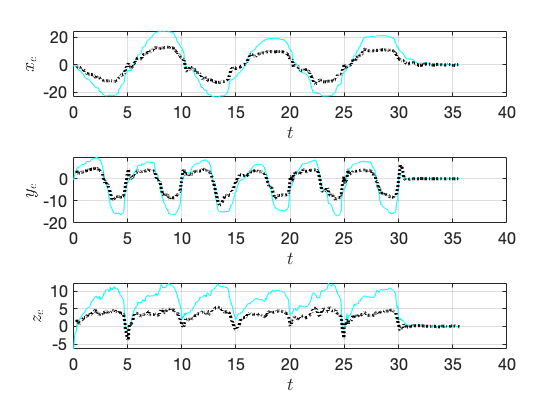

customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt); colororder(cool(length(indTest)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
% Plotting true position of tip
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(zu{iTraj,1},zu{iTraj,2}(iObs,:),'Linewidth',1)
    end
end

% Plotting estimated position of tip on SSM
for iTraj = 1:length(size(yDataRemapped, 1))
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        %plot(yDataRemapped{iTraj,1},yDataRemapped{iTraj,2}(outdofs(iObs),:),'k:','Linewidth',2)
        plot(yDataRemapped{iTraj,1},yDataRemapped{iTraj,2}(outdofs(iObs),:),'k:','Linewidth',2)
    end
end


% Plot SSM-approximated tip position by itself to see shape
% customFigure('subPlot',[numCoord 1]);
% subplot(numCoord,1,1);
% for iPlt = 1:length(outdofs)
%     subplot(numCoord,1,iPlt);
%     xlabel('$t$','Interpreter','latex');
%     ylabel(labels(iPlt),'Interpreter','latex');
% end
% for iTraj = 1:length(size(yDataRemapped, 1))
%     for iObs = 1:length(outdofs)
%         subplot(numCoord,1,iObs);
%         plot(yDataRemapped{iTraj,1},yDataRemapped{iTraj,2}(outdofs(iObs),:),'k:','Linewidth',2)
%     end
% end

normedTrajDataDist = computeTrajectoryErrors(yDataRemapped, yDataInput);
meanErrorGeoData = mean(normedTrajDataDist)*100

meanErrorGeoData = 16.0712

## Learn control matrix

% load koopman_data
% Consolidate data into standard var names and shift observation to origin
%z = y - y(:, end);
%zu{1,1} = t; zu{1,2} = z; 
%uCell{1,1} = t; uCell{1,2} = u;

%load koopman_data_figureEight

% Load and process tpwl data for tip coords only
load tpwl_data
y = y(13:end, :);

zu = {};
zu{1,1} = t; zu{1,2} = y - y(:, end); uCell{1,1} = t; uCell{1,2} = u;
% zu{2,1} = t; zu{2,2} = y - y_eq'; uCell{2,1} = t; uCell{2,2} = u;

% Project observables then lift (if required)
[Yu, yu_opts_embd] = coordinatesEmbeddingControl(zu, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


[Udelay, ~] = coordinatesEmbeddingControl(uCell, SSMDim, 'OverEmbedding', overEmbed, 'ndim', size([zu{1,2}], 1))

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


Udelay = 1×2 cell array
    {1×990 double}    {40×990 double}


uembedDim = size(Udelay{1,2},1);
udofs = [uembedDim-3, uembedDim-2 uembedDim-1 uembedDim];


YuData = []; UTrain = []; tTrain = [];
for iTraj = 1:size(Yu, 1)
    tStart = Yu{iTraj, 1}(1);
    [~, idxStart] = min( abs( zu{iTraj, 1}-tStart ) );
    
    % Concatenate times
    tcurrCenter = Yu{iTraj, 1} - Yu{iTraj, 1}(1);
    if isempty(tTrain)
        tcurrEnd = 0;
        tTrain = [tTrain, tcurrCenter];
    else
        tcurrEnd = tTrain(end); % End of previous time span
        tTrain = [tTrain, tcurrEnd + tcurrCenter(2:end)];
    end
    
    % Concatenate inputs
    UTrain = [UTrain, Udelay{iTraj,2}(udofs, :)];
    YuData = [YuData, Yu{iTraj,2}]; % No need to truncate (handled by coordsEmbedControl func)    
end

% Project lifted observation down to tangent space
xBarData = IMInfo.chart.map(YuData);

% Compute finite difference for data and truncate U to match dimensions
apprxOrd = 3;
[dXBarDt,xBarData,tTrain] = finiteTimeDifference(xBarData, tTrain, apprxOrd); % Truncates X_bar 3 places on each side
UTrain = UTrain(:, 1+apprxOrd:end-apprxOrd);

dXbarDt_aut = Rauton(xBarData); % Evaluate autonomous ROM dynamics for each Xbar

% Set options for ridgeRegression
varargin = {'R_PolyOrd', [3], 'style', 'default'};
nargin = 5;

L2 = 1 + 0 * exp(0*tTrain);

% Learn whole B matrix
[B_learn,l_opt,Err] = ridgeRegression(UTrain, dXBarDt - dXbarDt_aut, L2, [], 0); B_learn

B_learn = 	1.0e+03 *

   -0.1430   -0.1042   -0.0409    0.3266
   -0.3219   -0.7856   -0.1660    1.4362
    0.6632    0.3686    0.1818   -1.0346
   -1.7143    1.4496   -1.3463    0.8893
    0.5119   -0.3471    0.3573   -0.1175
    0.6180    0.4378    0.0616    0.4880


R = @(t,x,u) Rauton(x) + B_learn*u;

**Validate Control model**

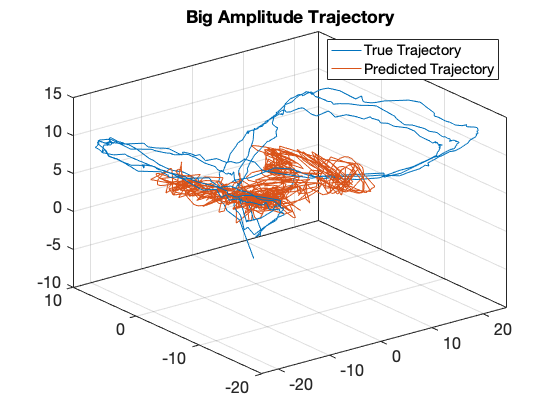

%load koopman_data_figureEight
% load koopman_data

% Load and process tpwl data for tip coords only
load tpwl_data
y = y(13:end, :);
y_eq = y_eq(13:end);

zTrue = y - y_eq';
tTrue = t;
uTrue = u'; % First dimension of interpolated value must be same size as t
uFun = @(t) transpose(interp1(tTrue, uTrue, t));
[tTraj,xTraj] = ode45(@(t,x) R(t,x,uFun(t)),tTrue,zeros(SSMDim,1)); % Assume we start at origin

xRecData = cell(1, 2); xRecData{1,1} = tTraj; xRecData{1,2} = xTraj';
yVal = liftTrajectories(IMInfo, xRecData);
zVal = yVal{1,2}(outdofs(1):outdofs(3),:);

% Visualize the trajectory in 3d
customFigure; 
plot3(zTrue(1, :), zTrue(2, :), zTrue(3, :));
plot3(zVal(1, :), zVal(2, :), zVal(3, :));
legend('True Trajectory', 'Predicted Trajectory');
title('Big Amplitude Trajectory');
view(3);

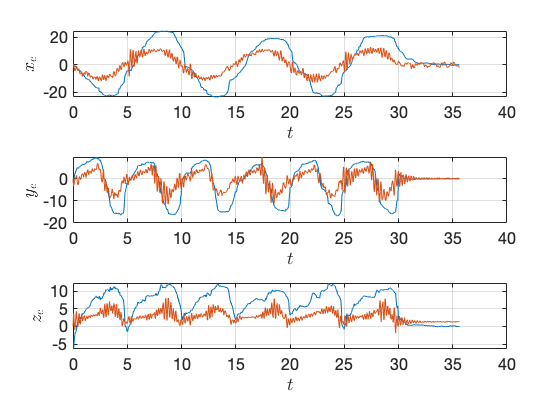


% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zTrue(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zVal(iObs, :),'Linewidth',1);
end

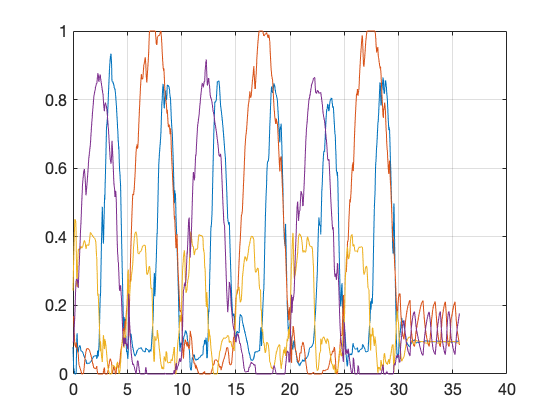


customFigure;
plot(tTrue, uTrue,'Linewidth',1);

**Validate short time Control model**

%load koopman_data_figureEight

% Load and process tpwl data for tip coords only
load tpwl_data
y = y(13:end, :);
y_eq = y_eq(13:end);

Nhoriz = 3;
zTrue = y - y_eq';
tTrue = t;
uTrue = u;

[yData, ~] = coordinatesEmbeddingControl({tTrue, zTrue}, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


nEval = length(yData{1,1})-Nhoriz;
yDataPredHoriz = cell(1,5);

etaData = yData;
for iTraj=1:size(etaData, 1)
    etaData{iTraj,2} = transpose(Vde)*yData{iTraj,2};
end
iRow = 1;
for iTime = 1:nEval
    uHoriz = uTrue(:,iTime:iTime+Nhoriz);
    tHoriz = tTrue(iTime:iTime+Nhoriz);
    uFun = @(t) transpose(interp1(tHoriz, transpose(uHoriz), t));
    [iTimeRec, ietaRec] = ode15s(@(t,x) R(t,x,uFun(t)),tHoriz,etaData{1,2}(:,iTime));
    % Lift
    iyRec = liftTrajectories(IMInfo, {iTimeRec, transpose(ietaRec)});
    
    yDataPredHoriz{iRow,1} = etaData{iTraj,1}(iTime:iTime+Nhoriz);
    yDataPredHoriz{iRow,2} = ietaRec(:,:);
    yDataPredHoriz{iRow,3} = etaData{iTraj,1}(iTime+Nhoriz);
    yDataPredHoriz{iRow,4} = iyRec{1,2}(outdofs,:);
    yDataPredHoriz{iRow,5} = iTime;
    iRow = iRow + 1;
end

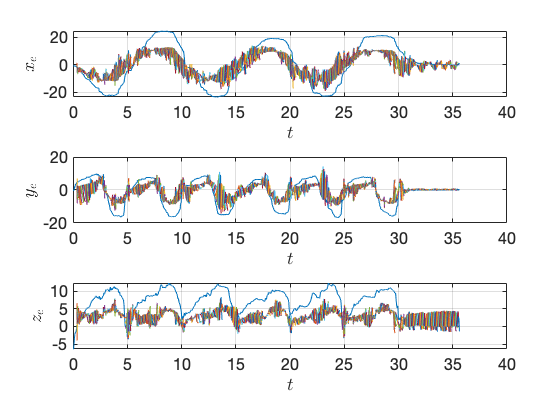

% Plot time series
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    plot(tTrue, zTrue(iObs, :),'Linewidth',1);
end
for iObs = 1:length(outdofs)
    subplot(numCoord,1,iObs);
    for iTraj=1:size(yDataPredHoriz,1)
        plot(yDataPredHoriz{iTraj,1}, yDataPredHoriz{iTraj,4}(iObs,:),'Linewidth',1);
    end
end